%{
ES115 Engineering Computer Applications
Module 3 Project: Autonomous Cart Speed Profile

Author: Zulaikha Khan  
Instructor: Lynroy Grant  
Date: March 28, 2026  

Purpose:
This project models the velocity of an autonomous cart over time using a
quadratic function. The goal is to analyze how the cart's speed changes,
determine when it reaches maximum velocity, and estimate acceleration
numerically. The project also compares velocity and acceleration behavior
using graphical representations.

Inputs (Knowns):
- Time values (t) from 0 to 20 seconds
- Velocity function: v(t) = -0.2(t - 10)^2 + 20
- Time step (Δt) = 0.2 seconds

Outputs (Unknowns):
- Velocity values over time
- Acceleration values calculated numerically
- Graph of velocity vs time
- Graph of acceleration vs time
- Maximum velocity and the time it occurs
- Acceleration near the point of maximum velocity

Engineering Workflow and Algorithms:
- Define time values over the given interval
- Use the quadratic function to compute velocity
- Plot velocity vs time
- Use numerical differentiation (finite difference) to estimate acceleration
- Adjust time values for acceleration data
- Plot acceleration vs time
- Find maximum velocity using MATLAB functions
- Evaluate acceleration near the maximum velocity point

MATLAB Tools / Functions Used:
- plot() for graphing
- diff() for numerical differentiation
- max() to find maximum velocity
- indexing to match values with time
- fprintf() for displaying results
- element-wise operations (.^) for calculations

Reflection After Completing the Project:
- I learned how velocity and acceleration are related and how acceleration
  can be estimated using numerical methods instead of derivatives.
- I also saw how the vertex of the velocity graph represents the maximum
  speed and how acceleration is close to zero at that point.
- If I were to improve this, I would compare the numerical acceleration to
  the exact derivative to see how accurate it is.
- Difficulty Rating: 5/10 — understanding the numerical differentiation
  took some effort, but the rest was straightforward.
%}



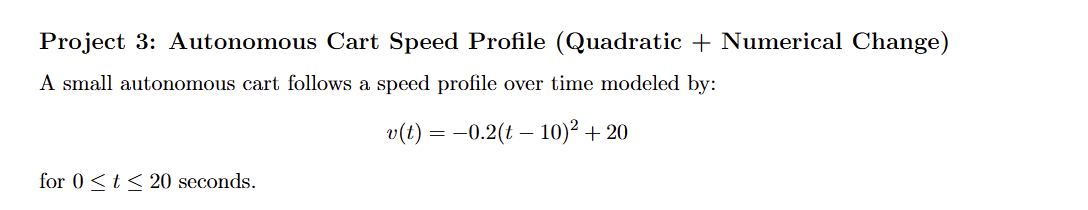

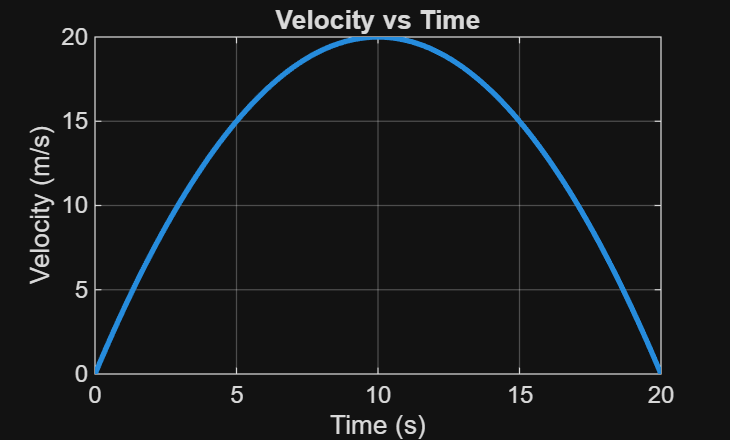


clear; clc; close all; 
% ---------------------------- 

% Define time values 
t = 0:0.2:20;  

% Velocity function 
v = -0.2*(t - 10).^2 + 20; 
% ---------------------------- 

% Plot velocity vs time 
figure; 
plot(t, v, 'LineWidth', 2); 

title('Velocity vs Time'); 
xlabel('Time (s)'); 
ylabel('Velocity (m/s)'); 
grid on;  

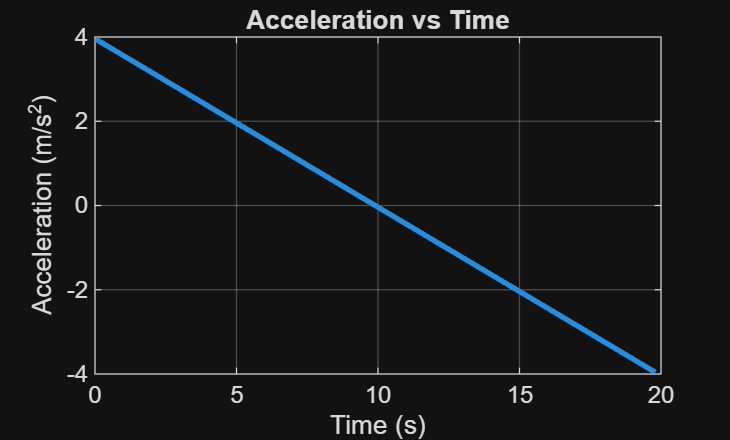

% ---------------------------- 

% Numerical acceleration (dv/dt) 
dt = 0.2; 
a = diff(v) / dt; 

% Adjust time for acceleration 
t_a = t(1:end-1); 
% ---------------------------- 

% Plot acceleration vs time 
figure; 
plot(t_a, a, 'LineWidth', 2); 

title('Acceleration vs Time'); 
xlabel('Time (s)'); 
ylabel('Acceleration (m/s^2)'); 
grid on; 

% ---------------------------- 

% Find maximum velocity 
[max_v, index] = max(v); 
t_max = t(index); 

fprintf('Maximum velocity: %.2f m/s at time %.2f seconds\n', max_v, t_max);   

Maximum velocity: 20.00 m/s at time 10.00 seconds


% ---------------------------- 

% Acceleration near max velocity 
accel_near_max = a(index); 
fprintf('Acceleration near max velocity: %.2f m/s^2\n', accel_near_max); 

Acceleration near max velocity: -0.04 m/s^2
